# Cosimulation of RoadRunner - Simulink

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear; 

## Launch RoadRunner from MATLAB

### *In order to access Simulink from RoadRunner, be sure to launch RoadRunner from MATLAB

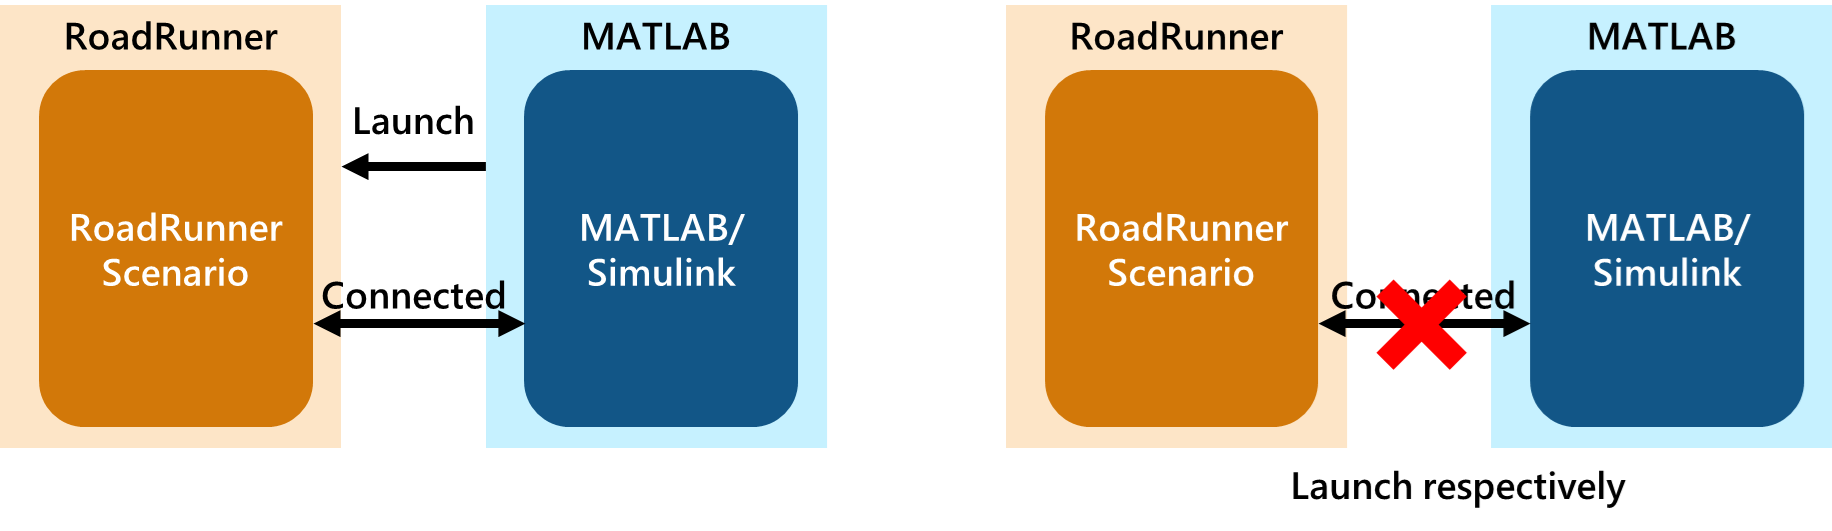

% If you are using a version earlier than R2024a, open the example with the following command and run it:
% openExample('autonomous_control/AuthorRoadRunnerActorUsingSimulinkExample')

rrApp = roadrunner();
rrProjectPath = rrApp.status.Project.Filename;
copyfile("RRfiles/TrajectoryCutInWithVariables.rrscenario",fullfile(rrProjectPath,"Scenarios/"));
copyfile("RRfiles/MySimulinkBehavior.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));

% Start the scenario. Scenes are linked to the scenario, so they are automatically opened as well
rrApp.openScenario("TrajectoryCutInWithVariables");

% Align the execution step size of RoadRunner and Simulink
simStepSize = 0.1;
rrSim = rrApp.createSimulation();
rrSim.set("StepSize", simStepSize);

% Define a Bus object to obtain RoadRunner information in Simulink.
% To support Reader and Writer blocks, some bus objects must be loaded
loadRoadRunnerBusObject();

% Vehicle position change constant
gainArg = [
    1 0 0 0.5;
    0 1 0 0.1;
    0 0 1 0;
    0 0 0 1];

% Open the Simulink model
model_name = 'SimulinkVehicle.slx';
open_system(model_name); 

## Add a Behavior file to the RoadRunner actor

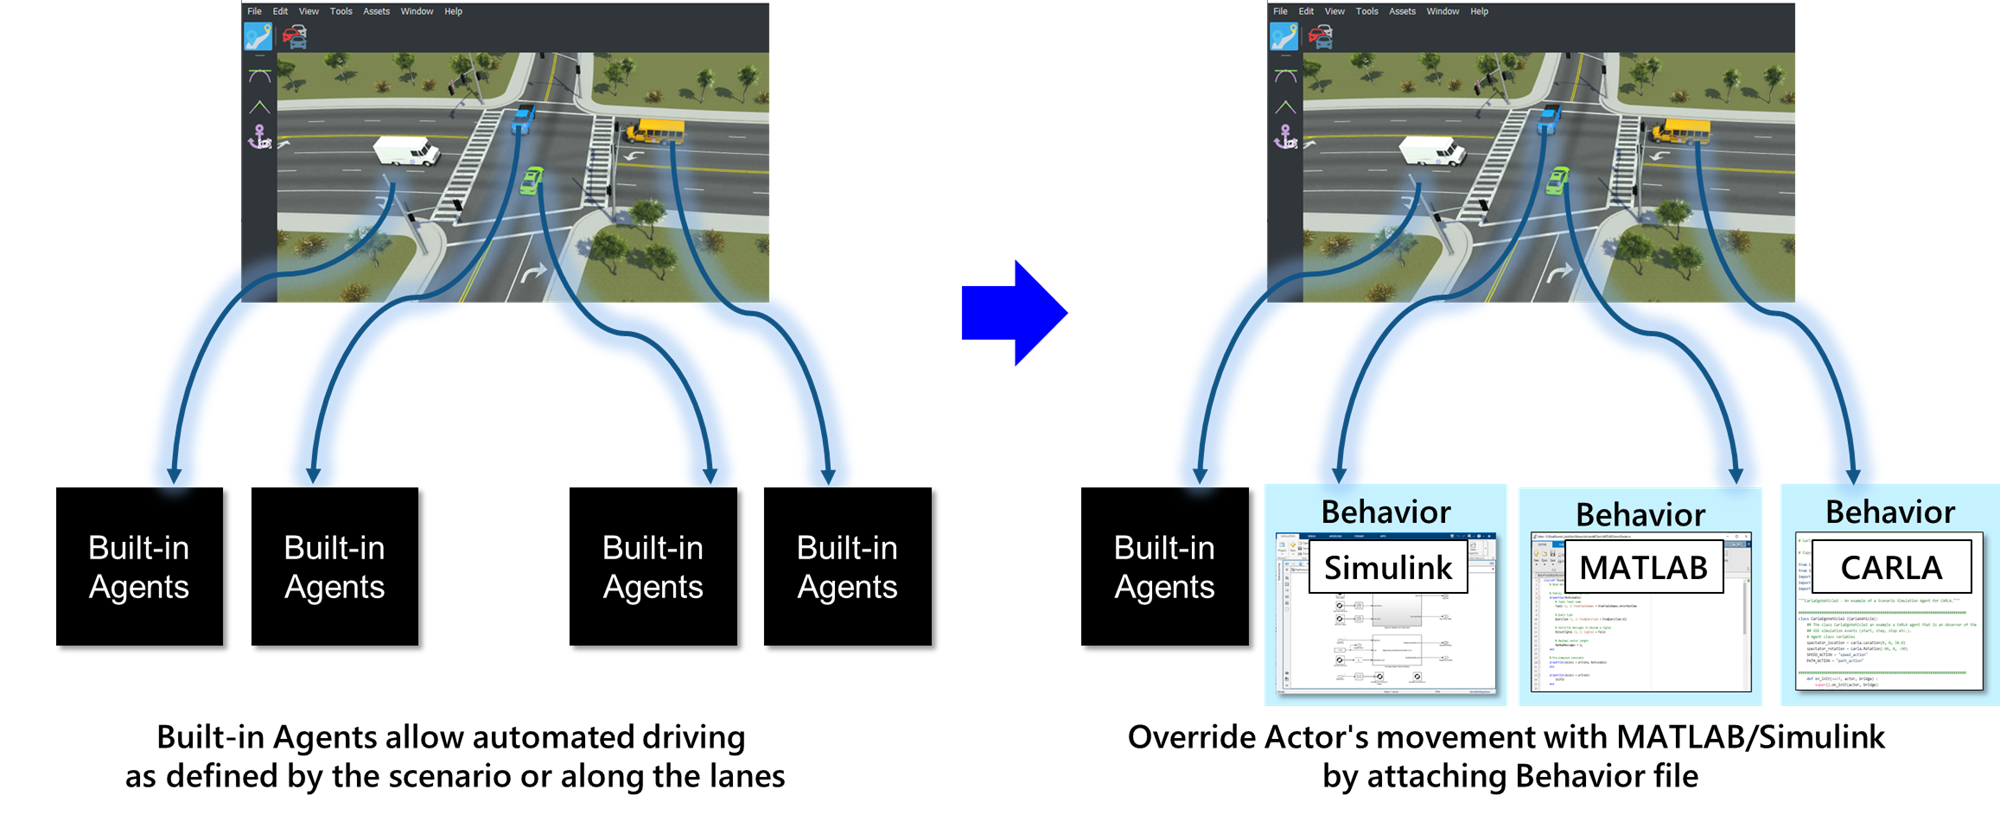

### Steps for setting a Behavior file to an actor and linking with Simulink

1. Create a Behavior file in RoadRunner's Library Browser (Note that this can only be created in SCENAIRIO EDITING!) 

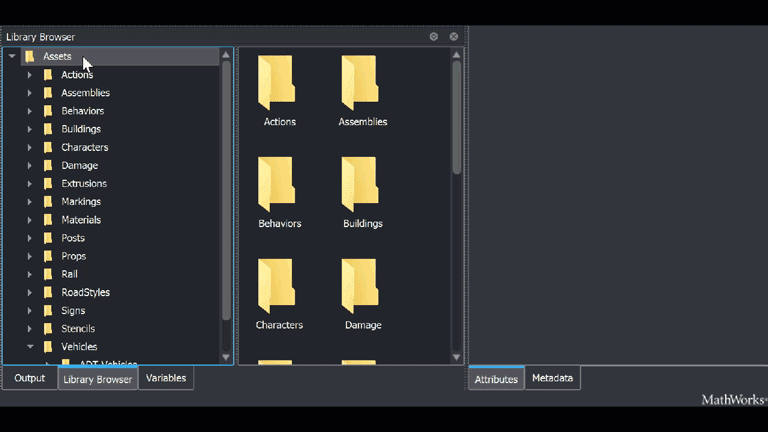

2. In the Attributes panel, set Platform to MATLAB/Simulink and enter the Simulink file name. 

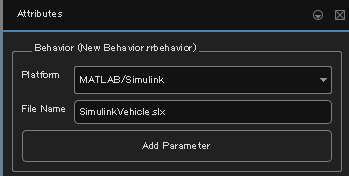

3. Click on the actor and drag and drop Behavior in the Attributes panel 

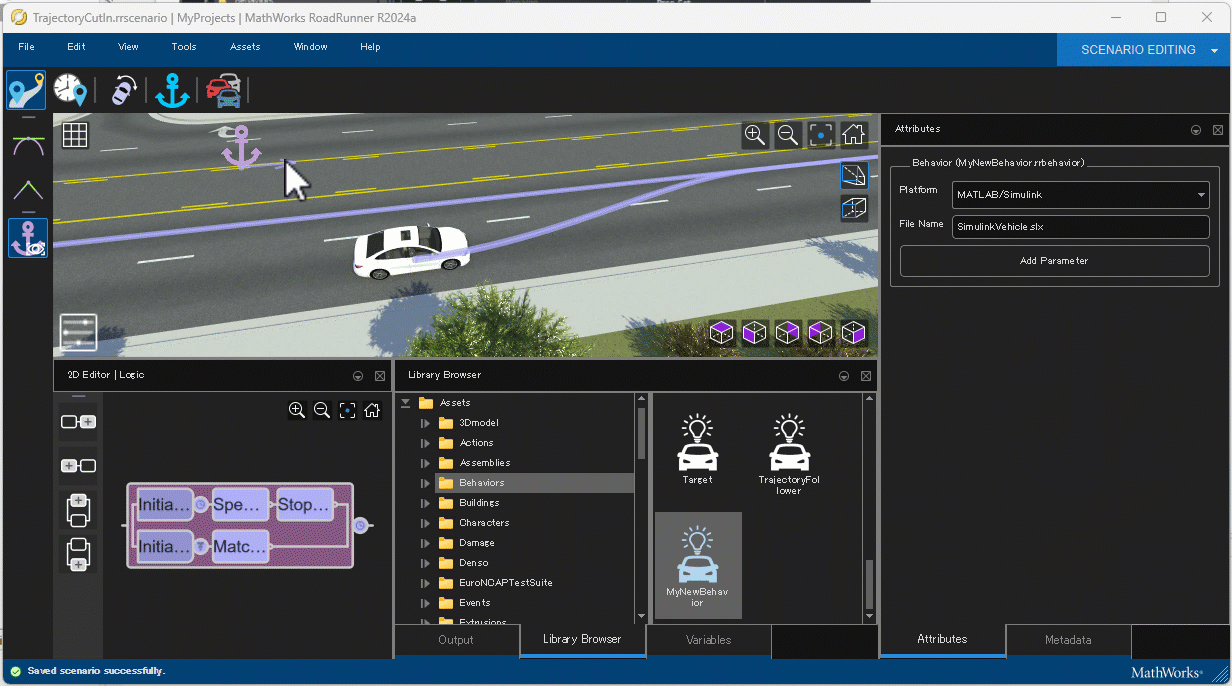

## Set behavior file from MATLAB

rrApp.setScenarioVariable("EgoBehavior", "<PROJECT>/Assets/Behaviors/MySimulinkBehavior.rrbehavior");

## Run RoadRunner

% Start the simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end 

## SimulinkVehicle.slx operation

SimulinkVehicle performs the following operations at each step 

1. Obtain the current posture from the RoadRunner actor (block [RoadRunner Scenario Reader](https://jp.mathworks.com/help/driving/ref/roadrunnerscenarioreader.html)), 

2. Add gainArg to the current posture (= add 0.5 m to the x position) 

3. Set the calculation result of 2 to the RoadRunner actor ( [RoadRunner Scenario Writer](https://jp.mathworks.com/help/driving/ref/roadrunnerscenariowriter.html) block). In addition to the actor posture, the 

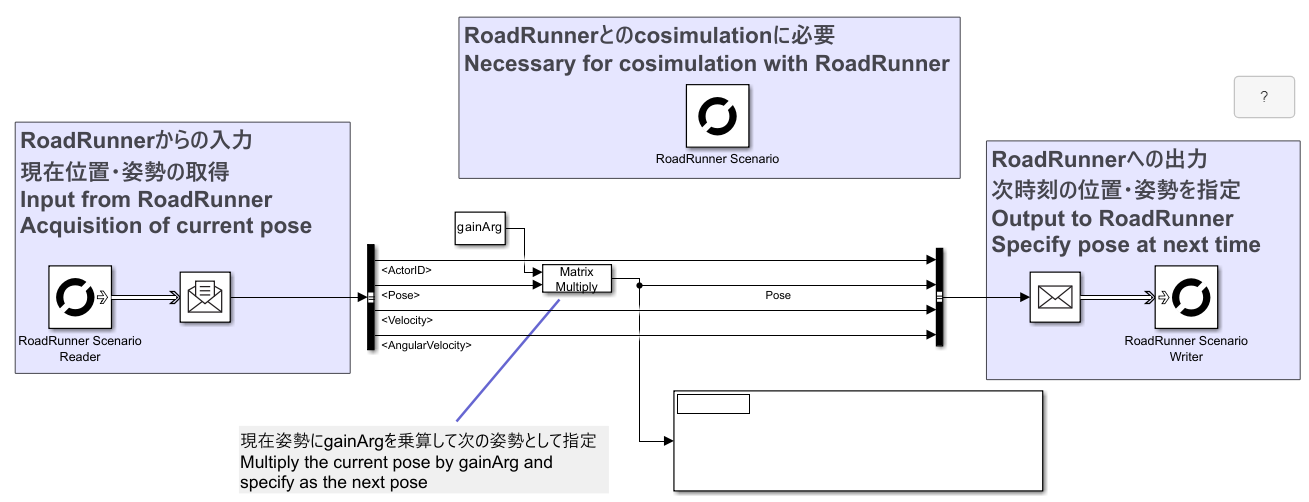

#### [RoadRunner Scenario Reader](https://jp.mathworks.com/help/driving/ref/roadrunnerscenarioreader.html)block and[RoadRunner Scenario Writer](https://jp.mathworks.com/help/driving/ref/roadrunnerscenariowriter.html) block can obtain actions such as paths defined in events and scenarios (for details, refer to the linked documentation) 

## Reference: Actor position and posture in RoadRunner Scenario

In RoadRunner Scenario, the current position and posture are expressed with a rigid body transformation matrix in a 4x4 homogeneous coordinate system 

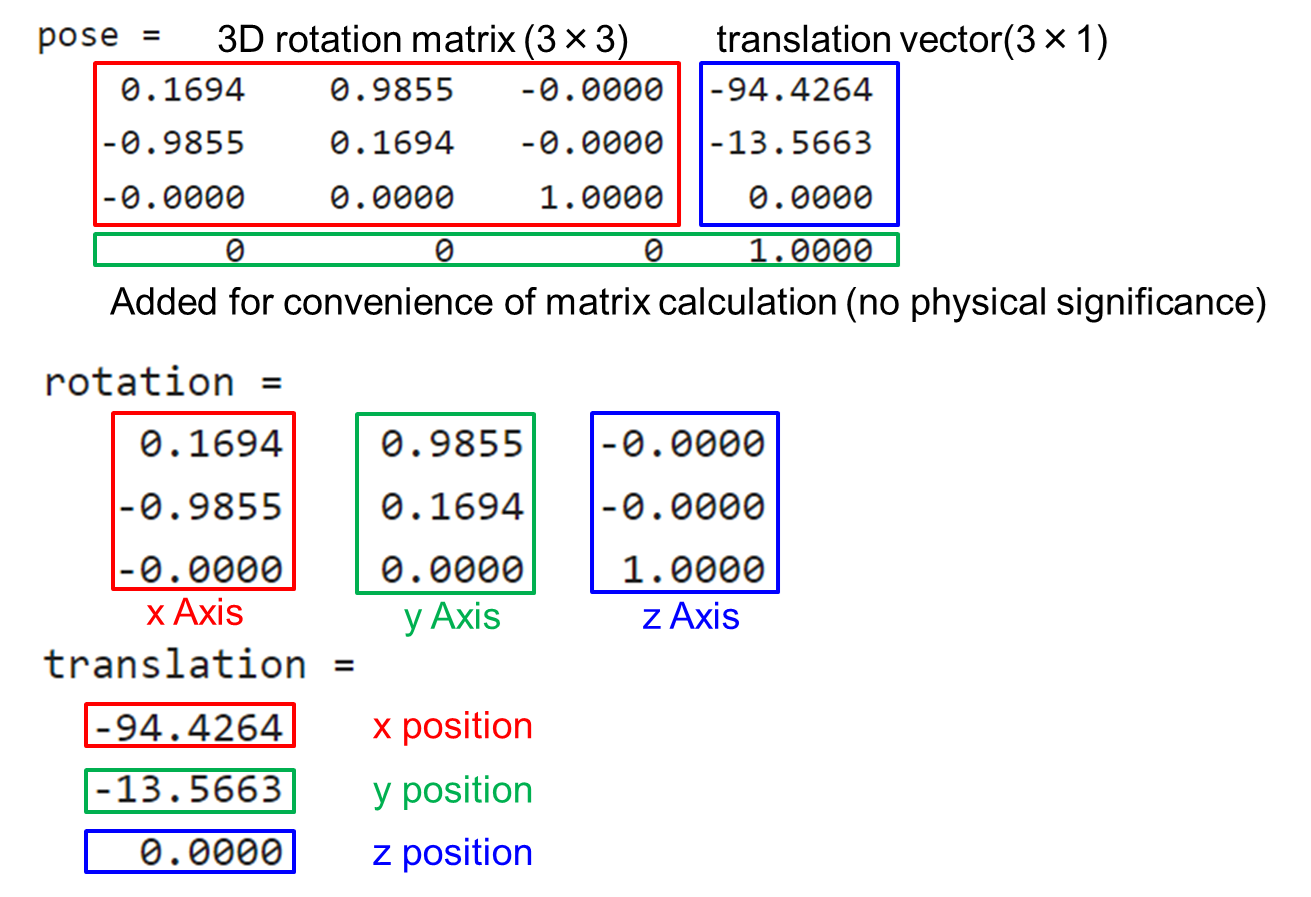

Example) When moving the x position 1 m 

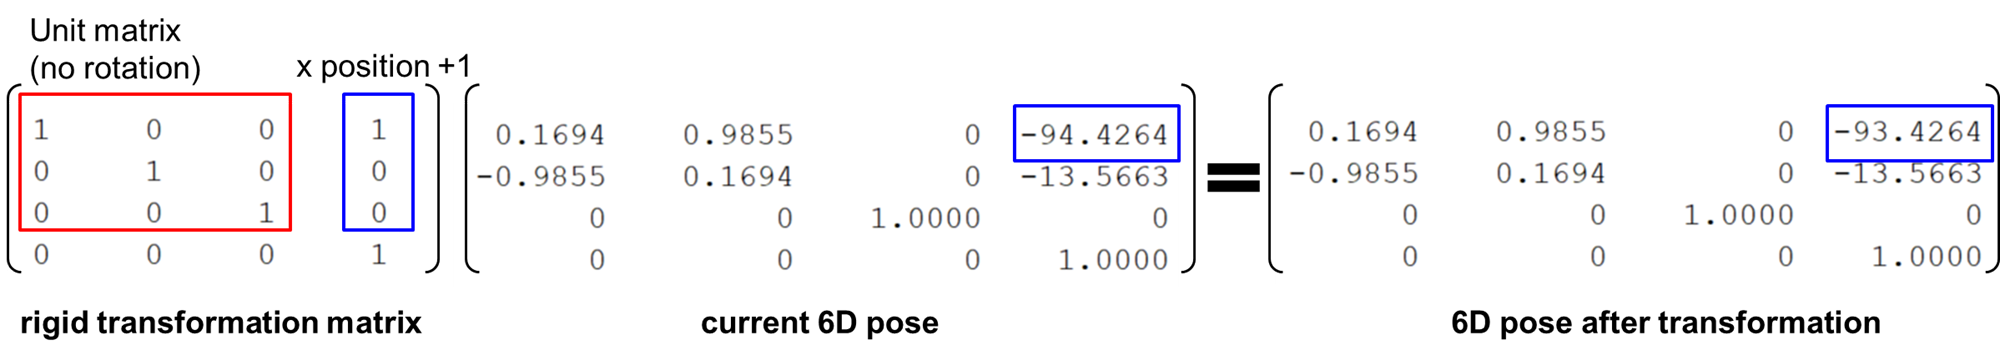

For details, refer to [This documentation](https://jp.mathworks.com/help/driving/ug/what-is-roadrunner-pose-matrix.html)  

## Advanced: Change the value of gainArg and check the difference in vehicle movement

% When changing the amount of movement in x, y, z
x_offset = 1;
y_offset = 0.1;
z_offset = 0.5;
gainArg(1,4) = x_offset;
gainArg(2,4) = y_offset;
gainArg(3,4) = z_offset;

% Start the simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end 

## Supplementary: Setting the execution step size in Simulink

The time for each step in Simulink can be set below 

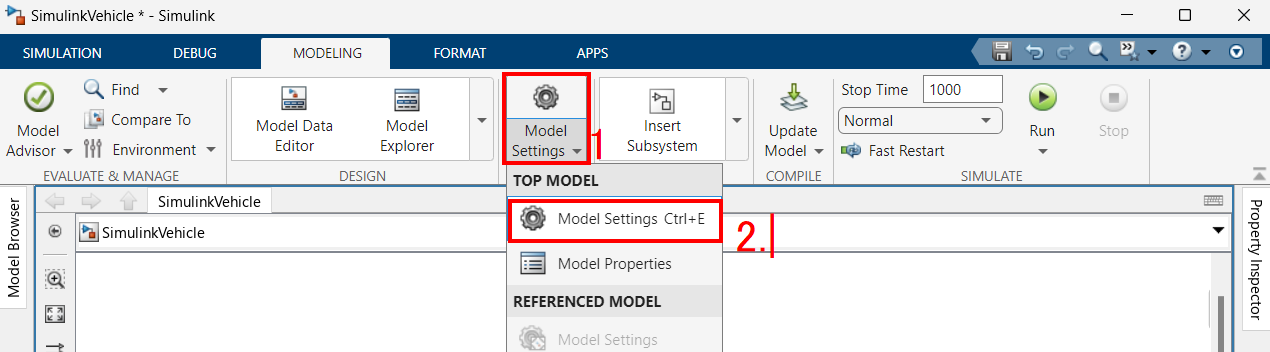

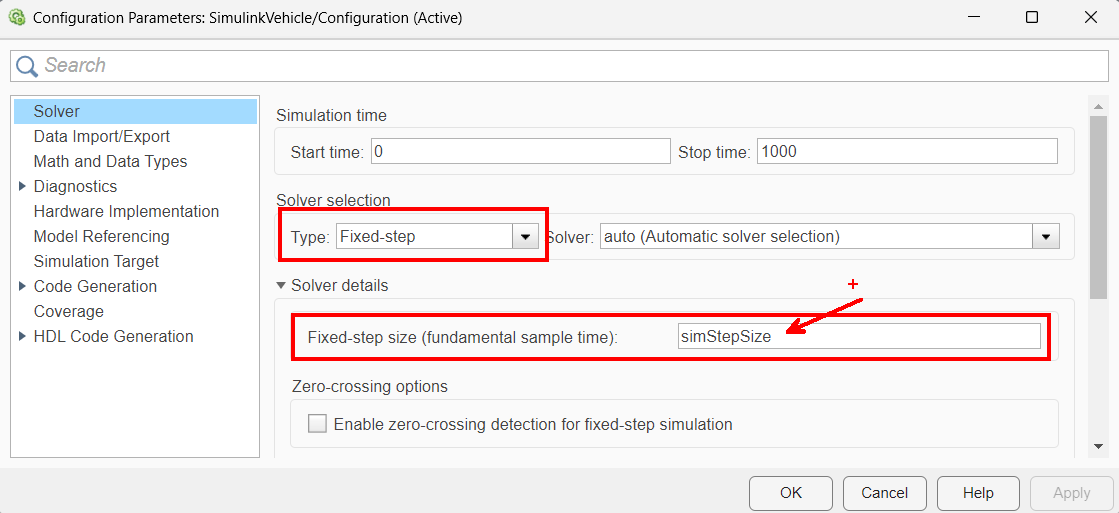

## Reference: Setting the execution step size in RoadRunner

The time for each step of RoadRunner can be set as follows: